# Entropy coefficient estimation - August 2023

**wmg, University of Warwick and KIT, Germany.**

**W.D. Widanage  (25/08/2023)**

## **Kernel based method**

clear

dataPth = what('Measurement_Data/measurements_Aug2023').path;
hdrNames = ["time", "TEC1", "TEC2", "BoxTop", "TabAnode", "SurfaceBottomAnode", "SurfaceTopAnode", "SurfaceBottomCathode", "SurfaceTopCathode", "TabCathode", "SurfaceTopCenter", "SurfaceBottomCenter", "CoolingBlockTop", "Ambient", "U"];
freqTextFilesInfo = dir(fullfile(dataPth,"*Frequency.txt"));
z = [0:5:100]; % SoC break points

for zz = 1:numel(z)
    kerObj(zz,1) = EntropyCoeffEstimator();
    kerObj(zz,1).ImportRefSig("filePth",fullfile(dataPth,"refSig","refSig_1050_July2022.mat"));             % Import reference signal
    kerObj(zz,1).ImportExpData("filePth",fullfile(dataPth,freqTextFilesInfo(zz).name),"HdrNames",hdrNames);
    disp(z(zz))
    kerObj(zz,1).EstimateEntropyCoeff("usePeriods",[1],"transientOnOff","on");
    if ~all(kerObj(zz,1).results.fitMetrics.LMRankFull)
        warning("Check SoC: %d",z(zz))
    end
    dUdTK(zz,1) = kerObj(zz,1).results.dUdT_mVpK;
    dUdTK_std(zz,1) = kerObj(zz,1).results.dUdT_std;
end

     0





Iteration terminated:  Parameter update is smaller than specified tolerance, TolDT = 1e-06.

LM Regressor rank deficient at iteration 31 
 Estimated parameters are unique.
Regressor preserves full rank. Rank =  5. 


     5





Iteration terminated:  Parameter update is smaller than specified tolerance, TolDT = 1e-06.

LM Regressor rank deficient at iteration 40 
 Estimated parameters are unique.
Regressor preserves full rank. Rank =  5. 


    10





Iteration terminated:  Parameter update is smaller than specified tolerance, TolDT = 1e-06.

LM Regressor rank deficient at iteration 20 
 Estimated parameters are unique.
Regressor preserves full rank. Rank =  4. 


    15





Iteration terminated:  Parameter update is smaller than specified tolerance, TolDT = 1e-06.

LM Regressor rank deficient at iteration 19 
 Estimated parameters are unique.
Regressor preserves full rank. Rank =  4. 


    20





Iteration terminated:  Parameter update is smaller than specified tolerance, TolDT = 1e-06.

LM Regressor rank deficient at iteration 38 
 Estimated parameters are unique.
Regressor preserves full rank. Rank =  5. 


    25





Iteration terminated:  Parameter update is smaller than specified tolerance, TolDT = 1e-06.

LM Regressor rank deficient at iteration 27 
 Estimated parameters are unique.
Regressor preserves full rank. Rank =  4. 


    30





Iteration terminated:  Parameter update is smaller than specified tolerance, TolDT = 1e-06.

LM Regressor rank deficient at iteration 52 
 Estimated parameters are unique.
Regressor preserves full rank. Rank =  6. 


    35





Iteration terminated:  Parameter update is smaller than specified tolerance, TolDT = 1e-06.

LM Regressor rank deficient at iteration 264 
 Estimated parameters are unique.
Regressor preserves full rank. Rank =  5. 


    40





Iteration terminated:  Parameter update is smaller than specified tolerance, TolDT = 1e-06.

LM Regressor rank deficient at iteration 18 
 Estimated parameters are unique.
Regressor preserves full rank. Rank =  5. 


    45





Iteration terminated:  Parameter update is smaller than specified tolerance, TolDT = 1e-06.

LM Regressor rank deficient at iteration 749 
 Estimated parameters are unique.
Regressor preserves full rank. Rank =  6. 


    50





Iteration terminated:  Parameter update is smaller than specified tolerance, TolDT = 1e-06.

LM Regressor rank deficient at iteration 22 
 Estimated parameters are unique.
Regressor preserves full rank. Rank =  4. 


    55





Iteration terminated:  Parameter update is smaller than specified tolerance, TolDT = 1e-06.

LM Regressor rank deficient at iteration 18 
 Estimated parameters are unique.
Regressor preserves full rank. Rank =  4. 


    60





Iteration terminated:  Parameter update is smaller than specified tolerance, TolDT = 1e-06.

LM Regressor rank deficient at iteration 14 
 Estimated parameters are unique.
Regressor preserves full rank. Rank =  4. 


    65





Iteration terminated:  Parameter update is smaller than specified tolerance, TolDT = 1e-06.

LM Regressor rank deficient at iteration 14 
 Estimated parameters are unique.
Regressor preserves full rank. Rank =  4. 


    70





Iteration terminated:  Parameter update is smaller than specified tolerance, TolDT = 1e-06.

LM Regressor rank deficient at iteration 14 
 Estimated parameters are unique.
Regressor preserves full rank. Rank =  5. 


    75





Iteration terminated:  Parameter update is smaller than specified tolerance, TolDT = 1e-06.

LM Regressor rank deficient at iteration 9 
 Estimated parameters are unique.
Regressor preserves full rank. Rank =  5. 


    80





Iteration terminated:  Maximum iteration reached, iterMax = 5000.

LM Regressor rank deficient at iteration 5000 
 Estimated parameters are NON-UNIQUE.
 Lls regressor is rank defficient. Rank = 5 instead of 6. 
Parameters estimated from a subspace. 


    85





Iteration terminated:  Parameter update is smaller than specified tolerance, TolDT = 1e-06.

LM Regressor rank deficient at iteration 15 
 Estimated parameters are unique.
Regressor preserves full rank. Rank =  4. 


    90





Iteration terminated:  Parameter update is smaller than specified tolerance, TolDT = 1e-06.

LM Regressor rank deficient at iteration 25 
 Estimated parameters are unique.
Regressor preserves full rank. Rank =  4. 


    95





Iteration terminated:  Parameter update is smaller than specified tolerance, TolDT = 1e-06.

LM Regressor rank deficient at iteration 28 
 Estimated parameters are unique.
Regressor preserves full rank. Rank =  4. 


   100





Iteration terminated:  Parameter update is smaller than specified tolerance, TolDT = 1e-06.

LM Regressor rank deficient at iteration 17 
 Estimated parameters are unique.
Regressor preserves full rank. Rank =  4. 



% Improve fit for low GoFs
plot_soc = 10;
idx = find(plot_soc == z);
kerObj(idx,1).EstimateEntropyCoeff("usePeriods",1,"transientOnOff","on","modelOrder_num",2,"modelOrder_denom",3,freqIdx_estimation=(1:5));



Iteration terminated:  Parameter update is smaller than specified tolerance, TolDT = 1e-06.

LM Regressor rank deficient at iteration 998 
 Estimated parameters are unique.
Regressor preserves full rank. Rank =  6. 



plot_soc = 20;
idx = find(plot_soc == z);
kerObj(idx,1).EstimateEntropyCoeff("usePeriods",1,"transientOnOff","on","modelOrder_num",2,"modelOrder_denom",3,freqIdx_estimation=(1:5));



Iteration terminated:  Parameter update is smaller than specified tolerance, TolDT = 1e-06.

LM Regressor rank deficient at iteration 1174 
 Estimated parameters are unique.
Regressor preserves full rank. Rank =  6. 



plot_soc = 25;
idx = find(plot_soc == z);
kerObj(idx,1).EstimateEntropyCoeff("usePeriods",1,"transientOnOff","on","modelOrder_num",2,"modelOrder_denom",3,freqIdx_estimation=(1:5));



Iteration terminated:  Parameter update is smaller than specified tolerance, TolDT = 1e-06.

LM Regressor rank deficient at iteration 526 
 Estimated parameters are unique.
Regressor preserves full rank. Rank =  6. 


kerObj(idx).results.fitMetrics.FitPercent

ans = 98.6639



plot_soc = 30;
idx = find(plot_soc == z);
kerObj(idx,1).EstimateEntropyCoeff("usePeriods",1,"transientOnOff","on","modelOrder_num",2,"modelOrder_denom",3,freqIdx_estimation=(1:5));



Iteration terminated:  Parameter update is smaller than specified tolerance, TolDT = 1e-06.

LM Regressor rank deficient at iteration 1904 
 Estimated parameters are unique.
Regressor preserves full rank. Rank =  6. 



plot_soc = 95;
idx = find(plot_soc == z);
kerObj(idx,1).EstimateEntropyCoeff("usePeriods",1,"transientOnOff","on","modelOrder_num",2,"modelOrder_denom",3,freqIdx_estimation=(1:5));



Iteration terminated:  Parameter update is smaller than specified tolerance, TolDT = 1e-06.

LM Regressor rank deficient at iteration 2728 
 Estimated parameters are unique.
Regressor preserves full rank. Rank =  6. 



% Re-collect kernel based dUdT and the standard deviation and fit metrics
for zz = 1:length(z)
    dUdTK(zz,1) = kerObj(zz,1).results.dUdT_mVpK;
    dUdTK_std(zz,1) = kerObj(zz,1).results.dUdT_std;

    % Collect GoF, model order and full-rank status
    GoF(zz,1) = kerObj(zz).results.fitMetrics.FitPercent;
    RMSE(zz,1) = kerObj(zz).results.fitMetrics.RMSE;
    full_rank(zz,1) = kerObj(zz,1).results.fitMetrics.LMRankFull(end);

    model_order(zz,:) = [kerObj(zz).estimationSettings.modelOrder_num,kerObj(zz).estimationSettings.modelOrder_denom]; 
   
end


## Potentiometric based method

potDuration = 17.1472

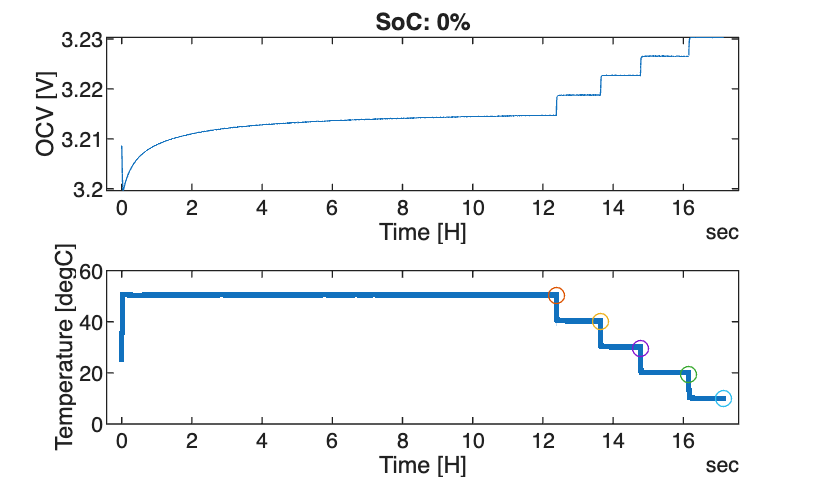

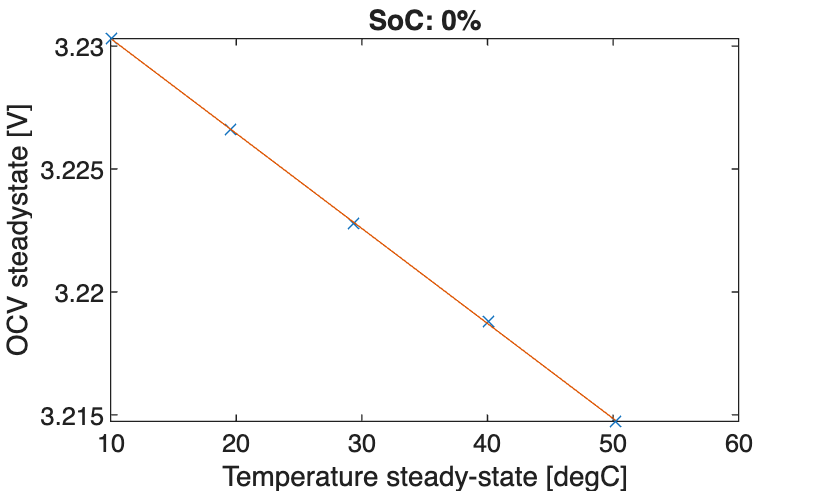

potDuration = 13.9006

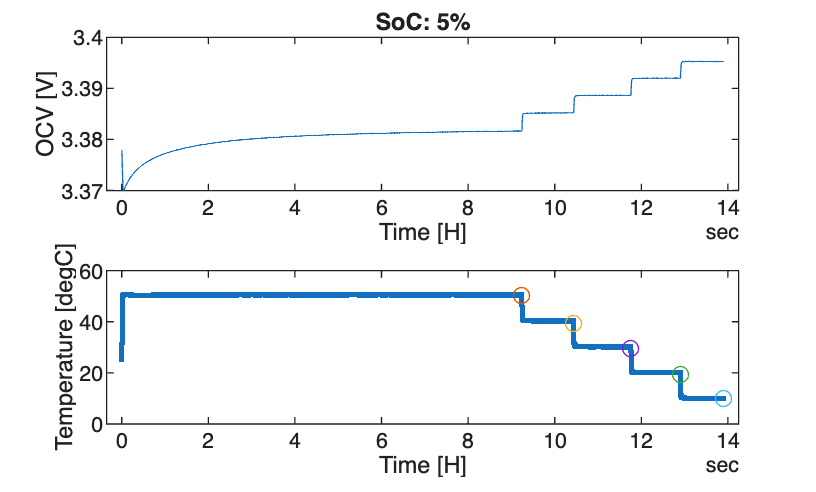

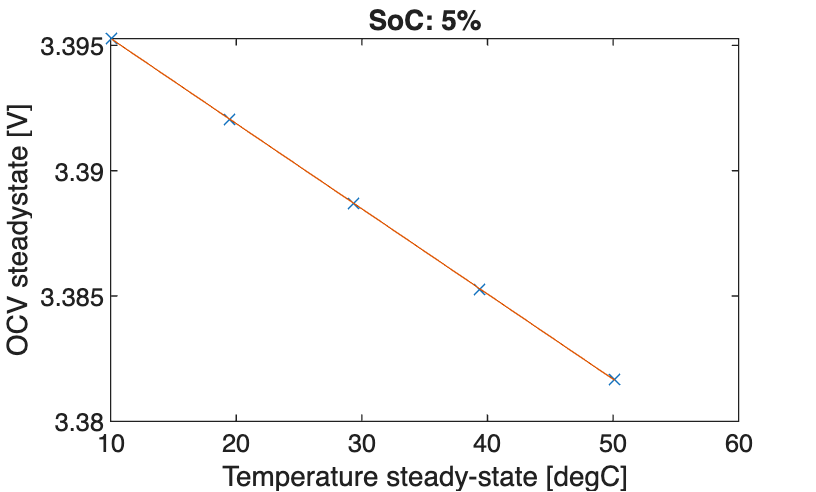

potDuration = 5.0223

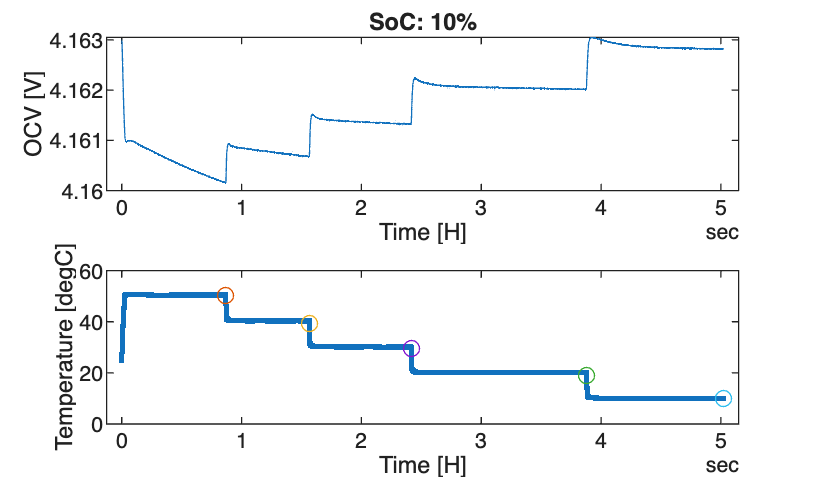

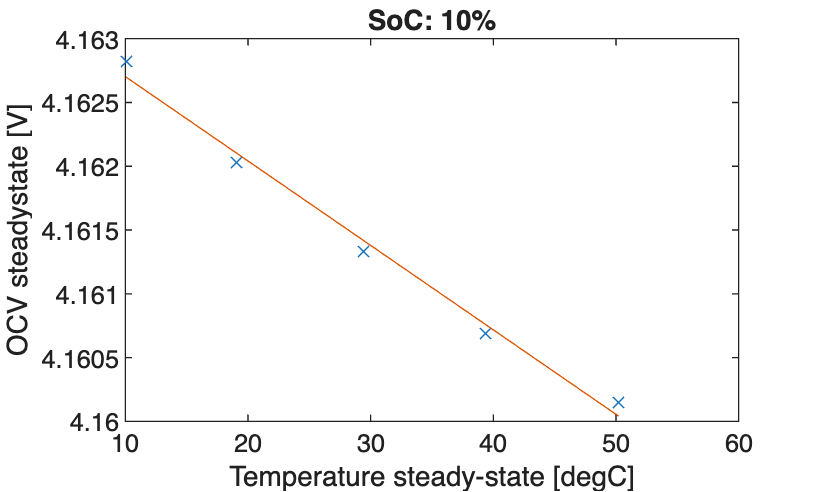

potDuration = 14.6267

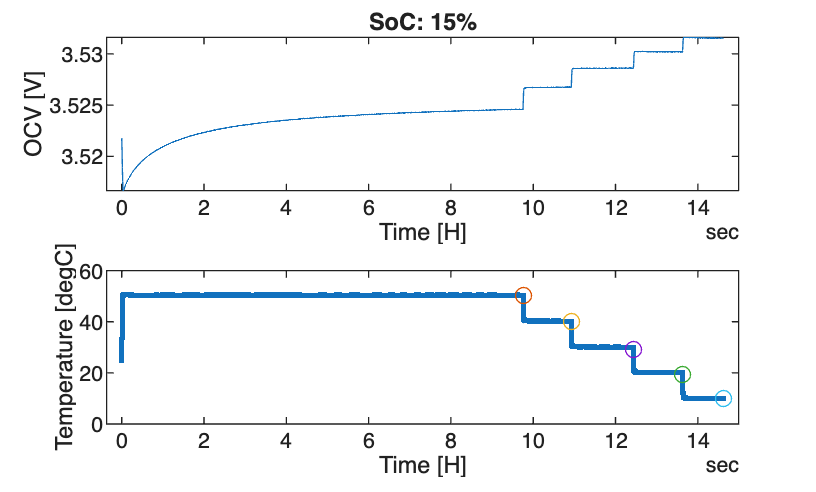

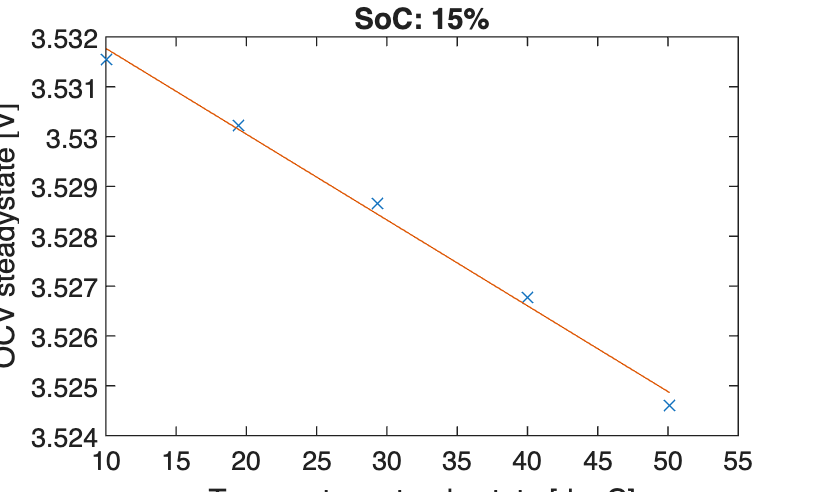

potDuration = 13.4844

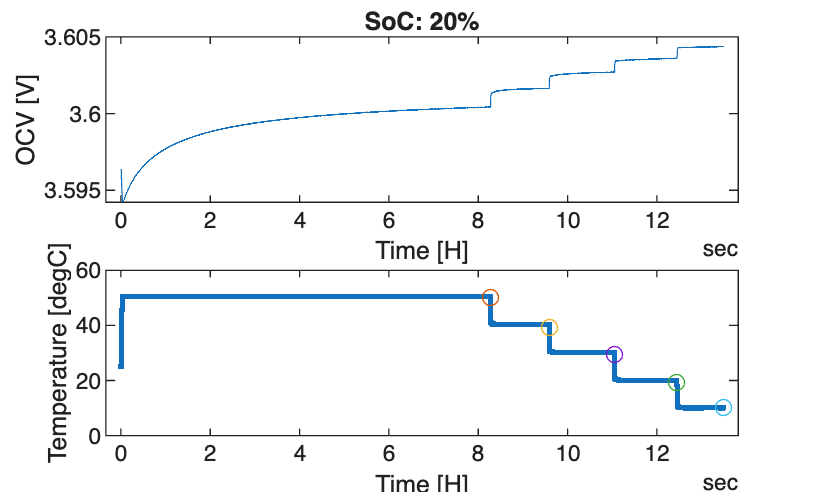

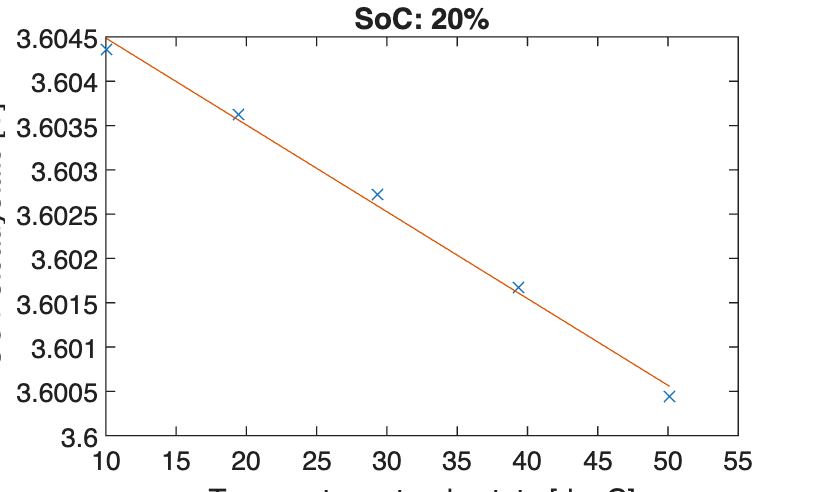

potDuration = 16.4291

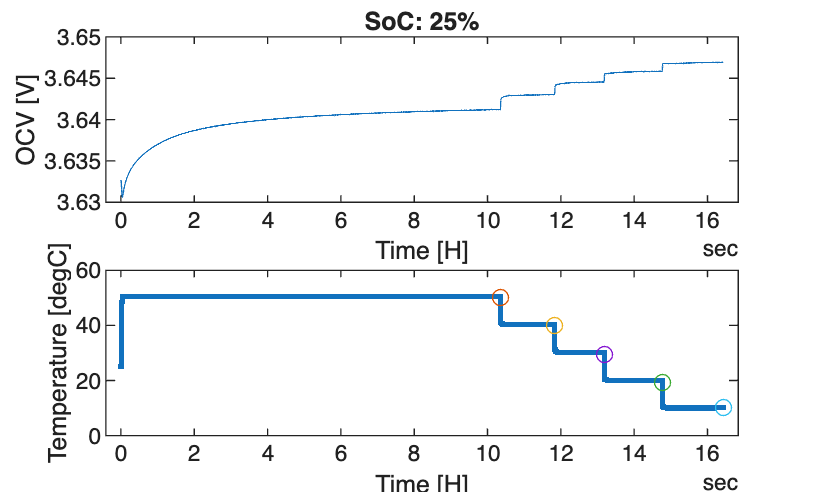

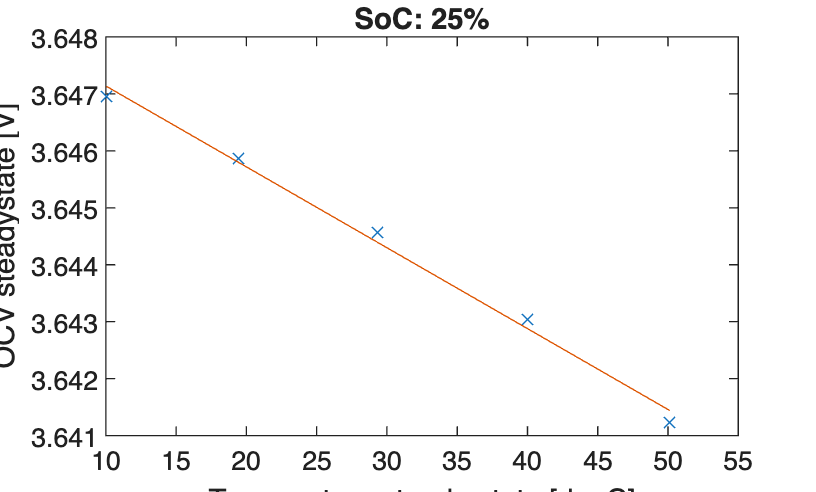

potDuration = 7.0244

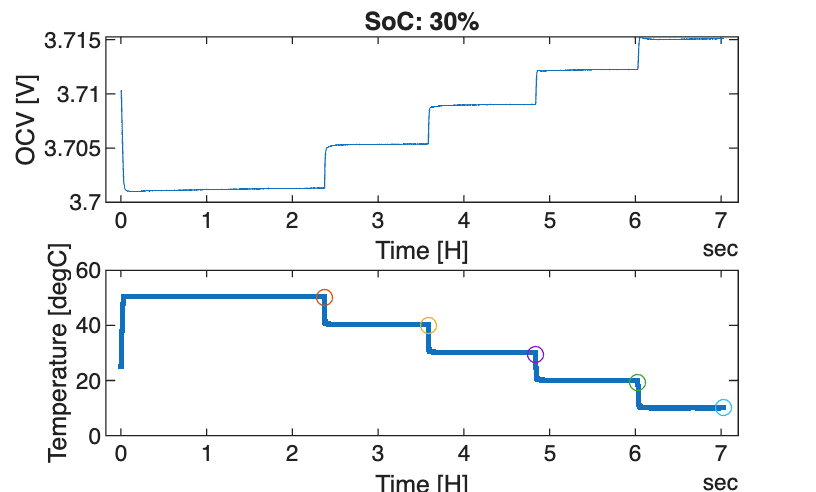

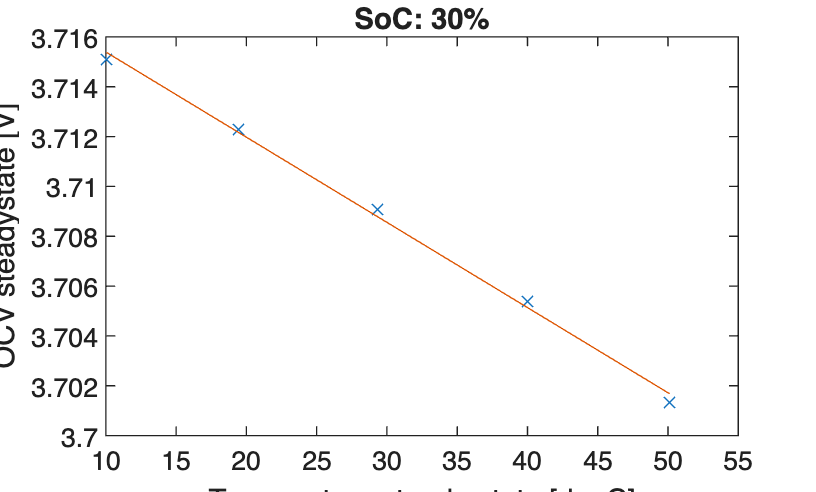

potDuration = 8.9045

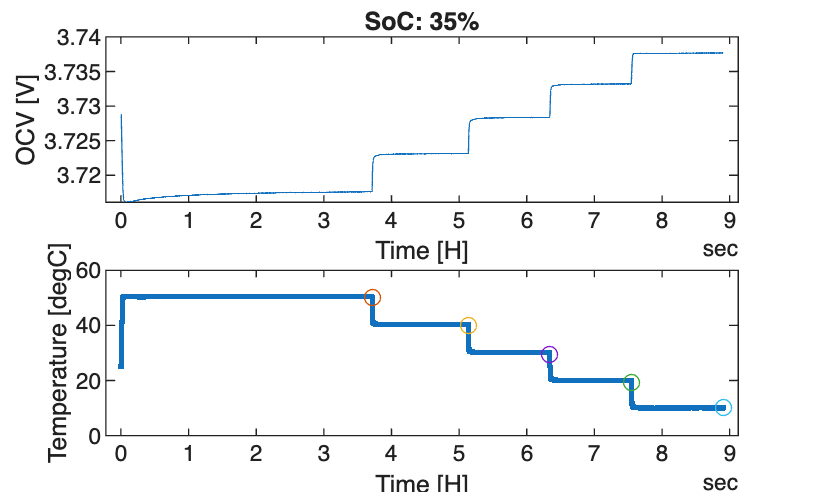

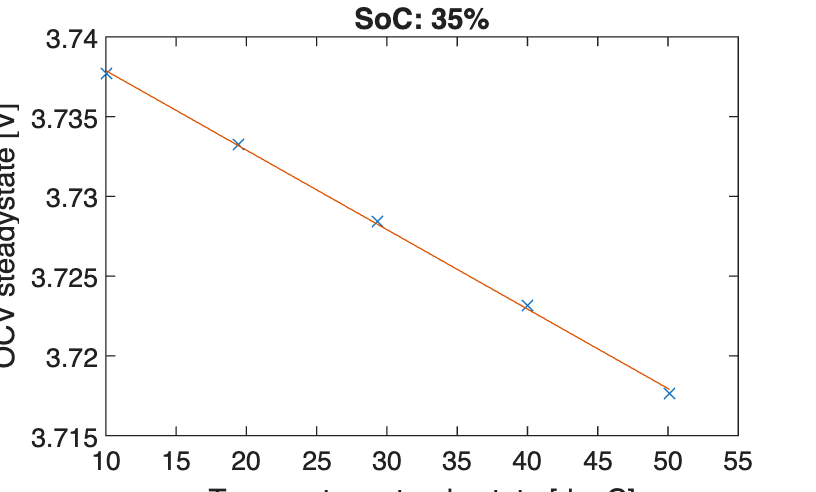

potDuration = 6.9433

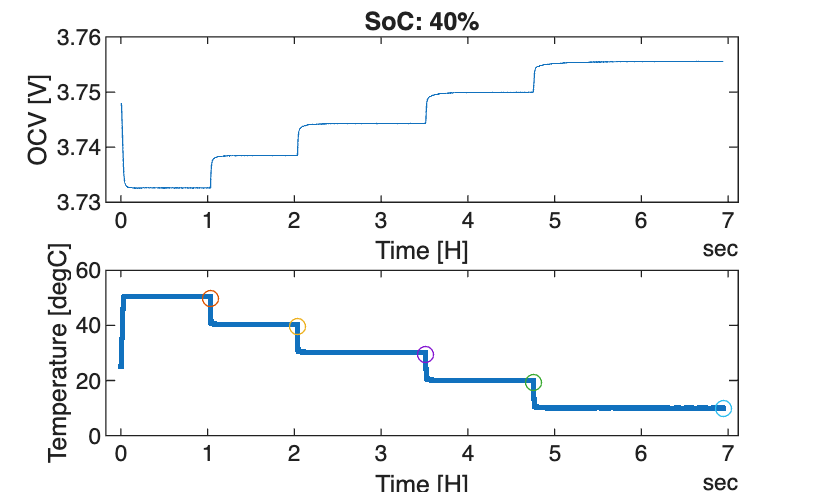

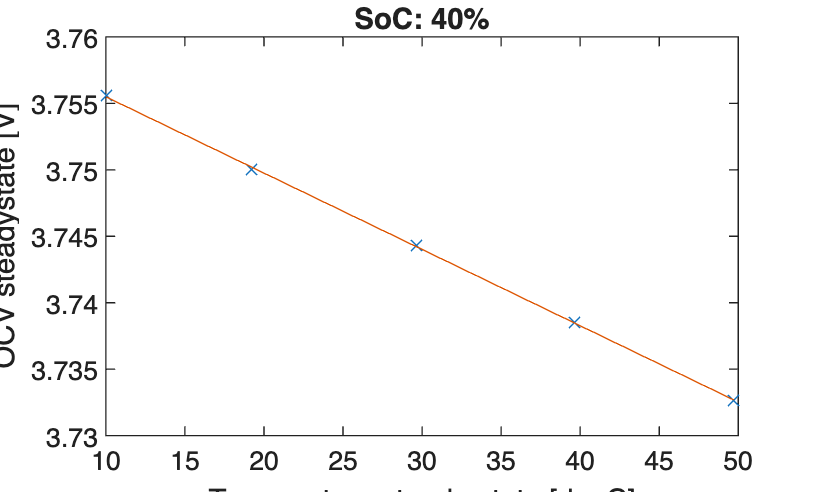

potDuration = 14.6472

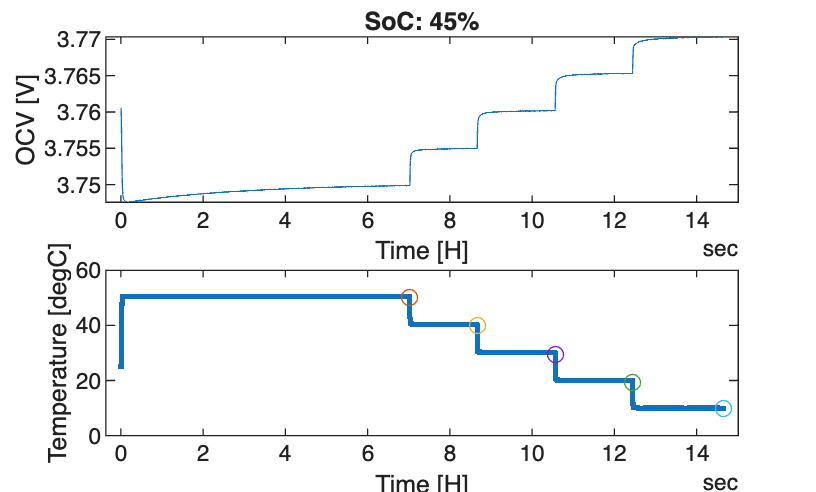

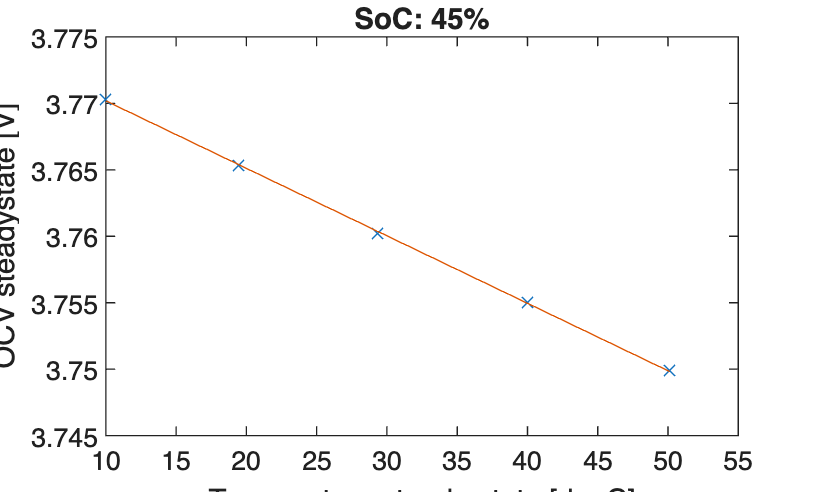

potDuration = 7.9750

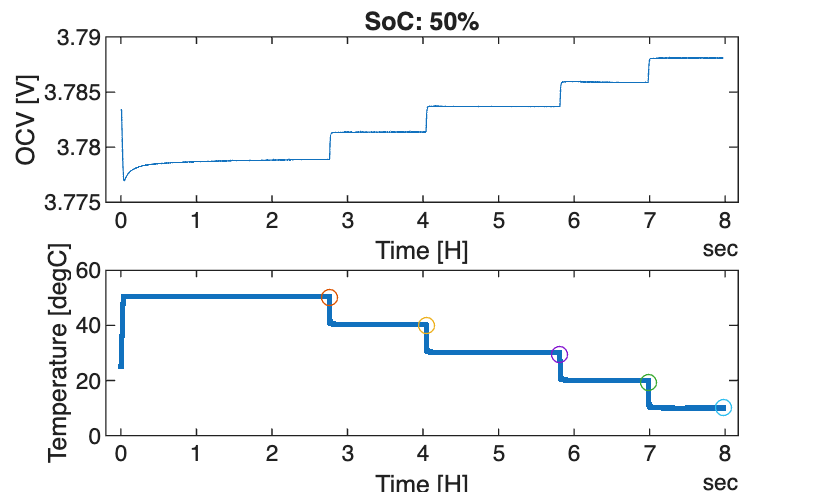

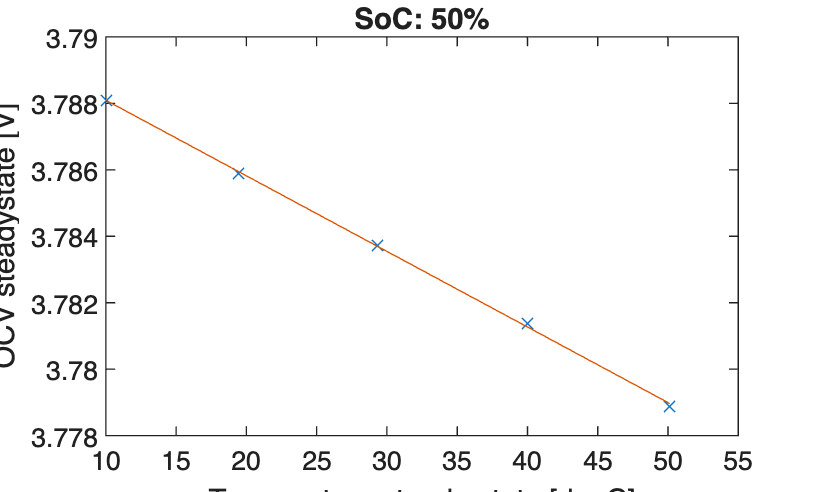

potDuration = 7.7072

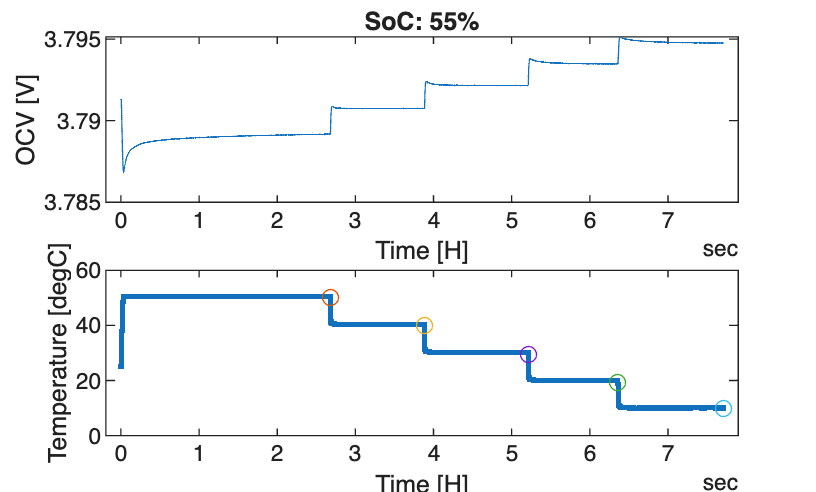

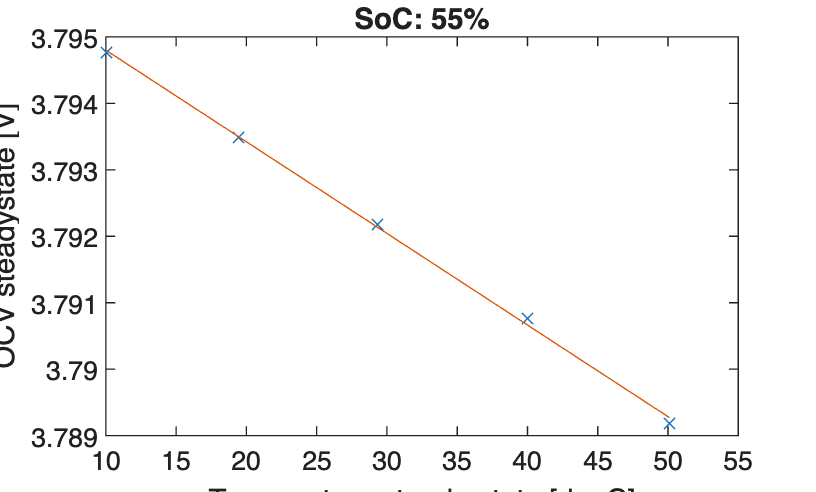

potDuration = 6.6022

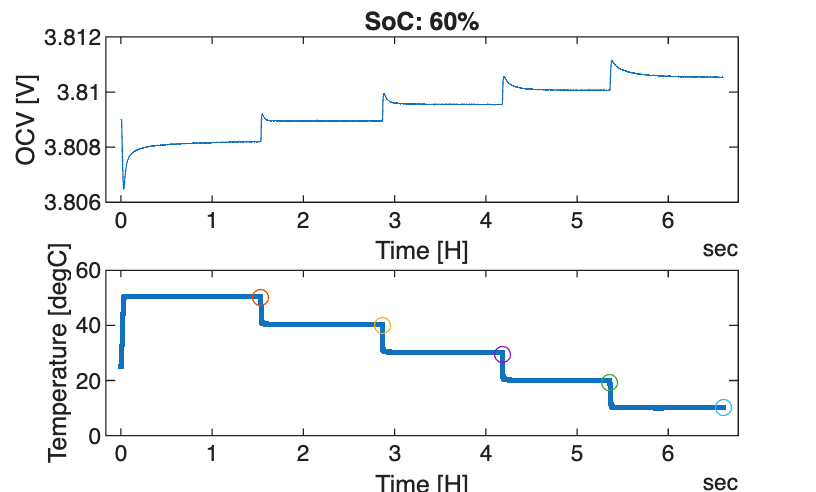

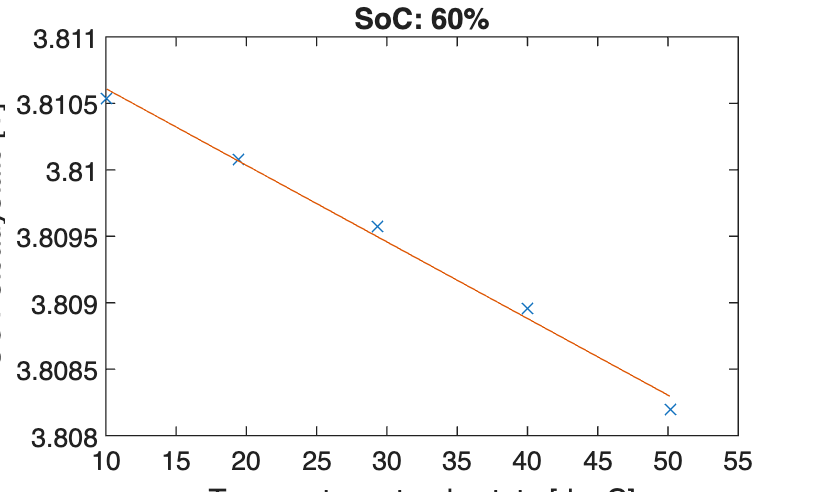

potDuration = 8.4117

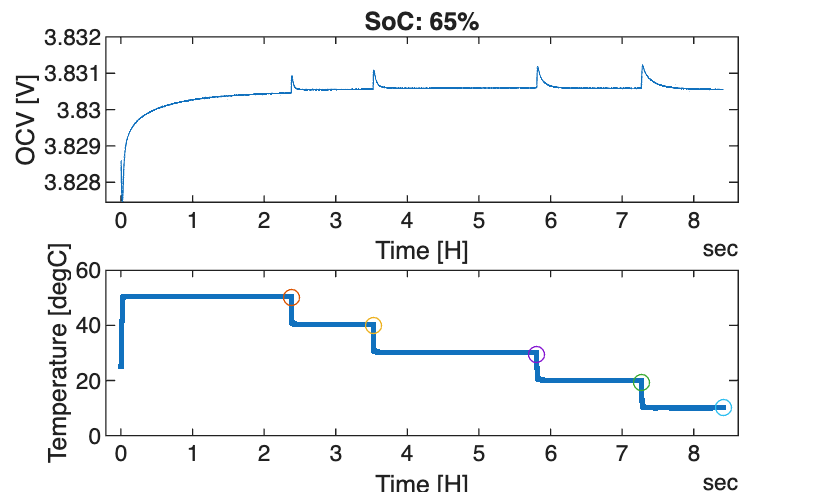

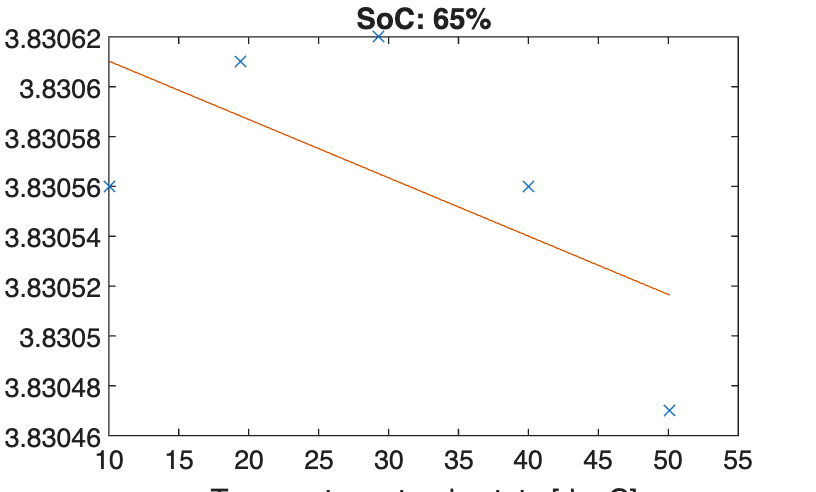

potDuration = 6.4217

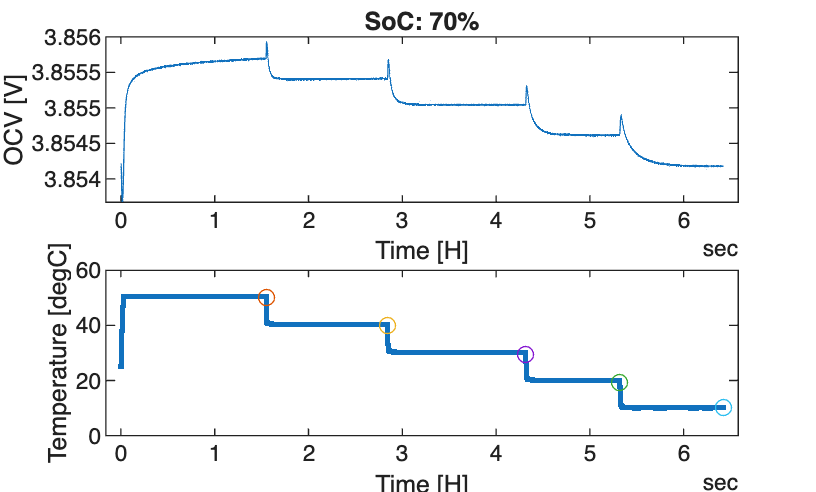

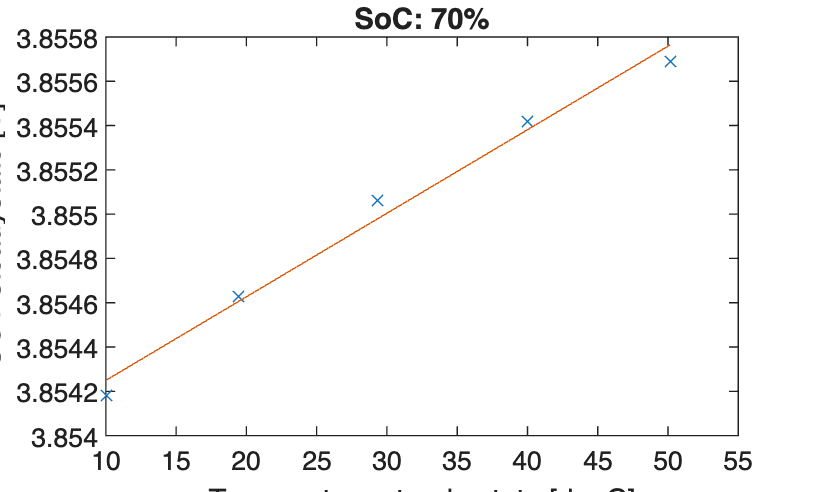

potDuration = 6.9294

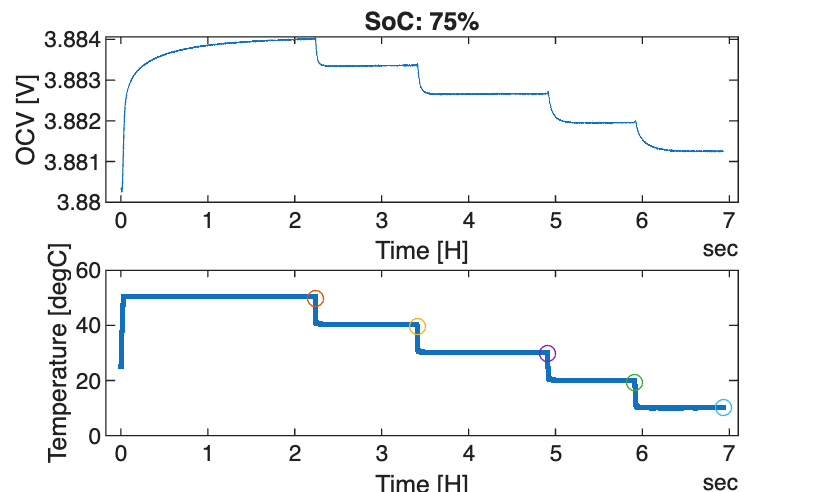

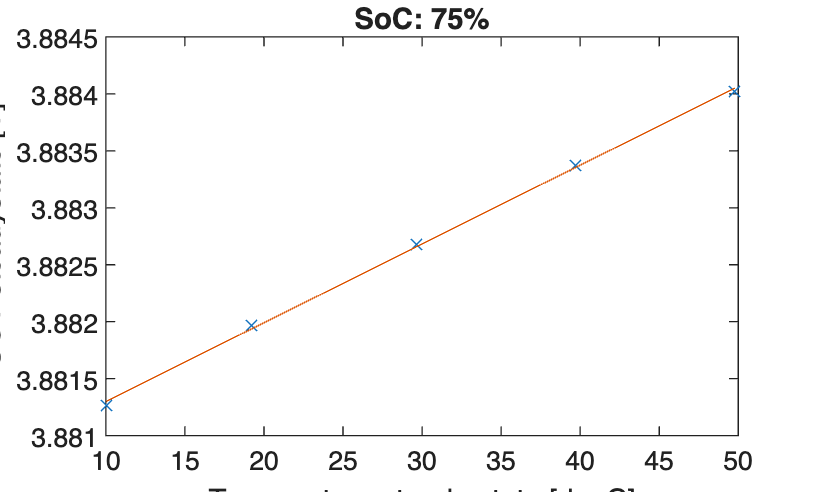

potDuration = 6.7683

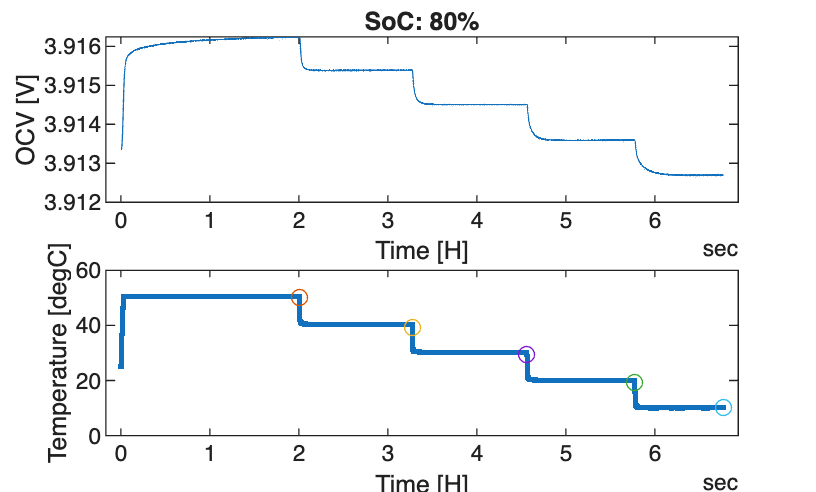

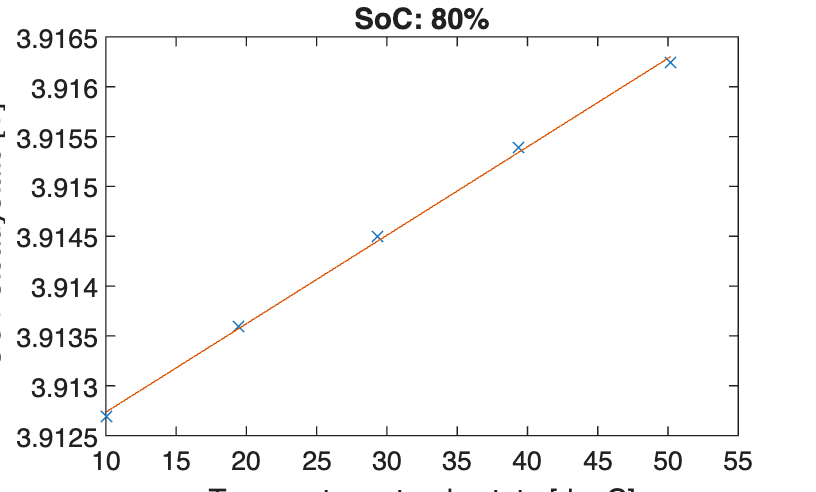

potDuration = 5.8783

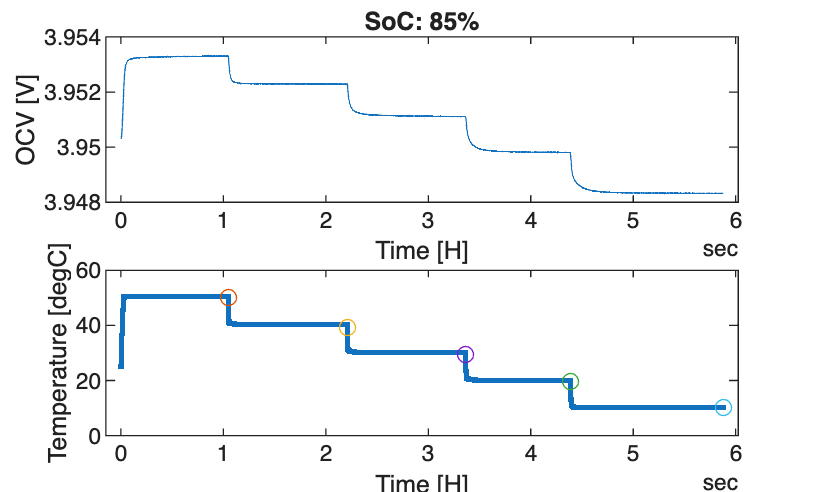

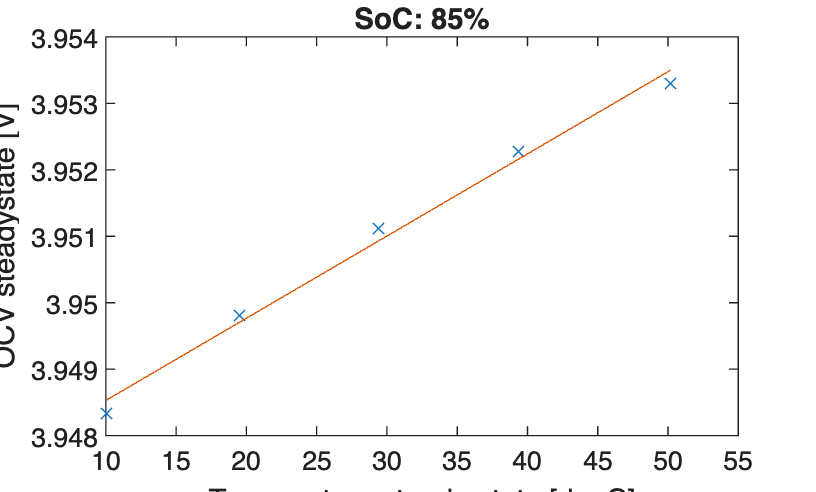

potDuration = 6.5811

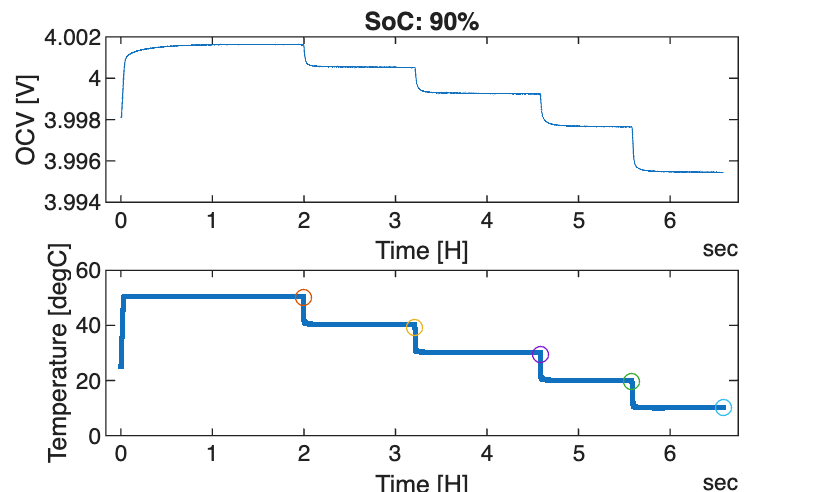

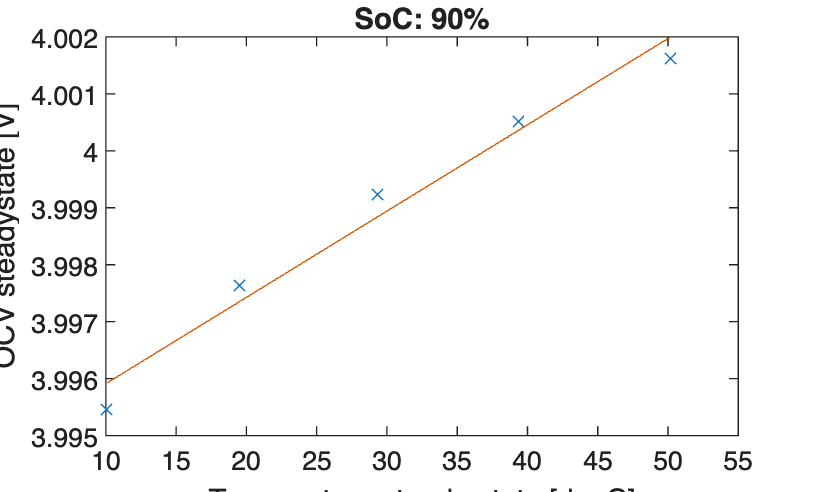

potDuration = 6.5367

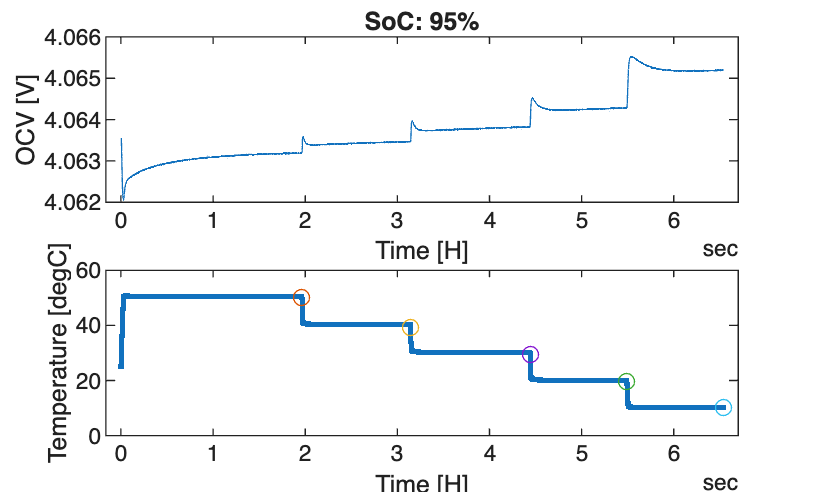

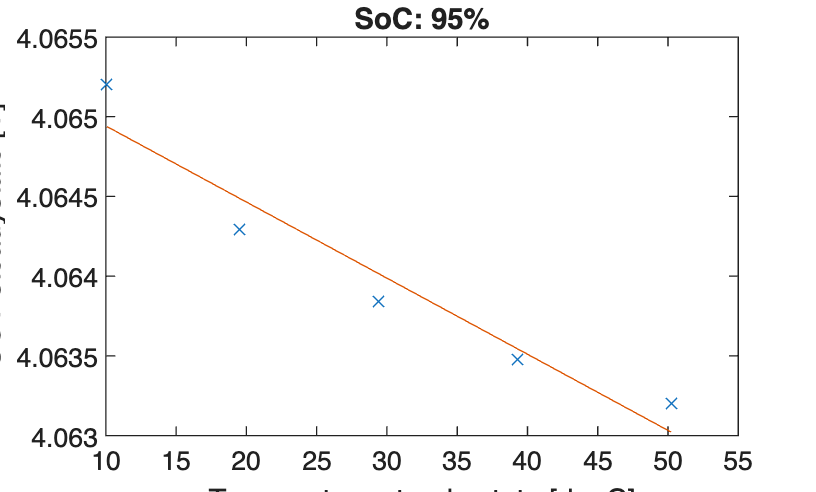

potDuration = 6.3328

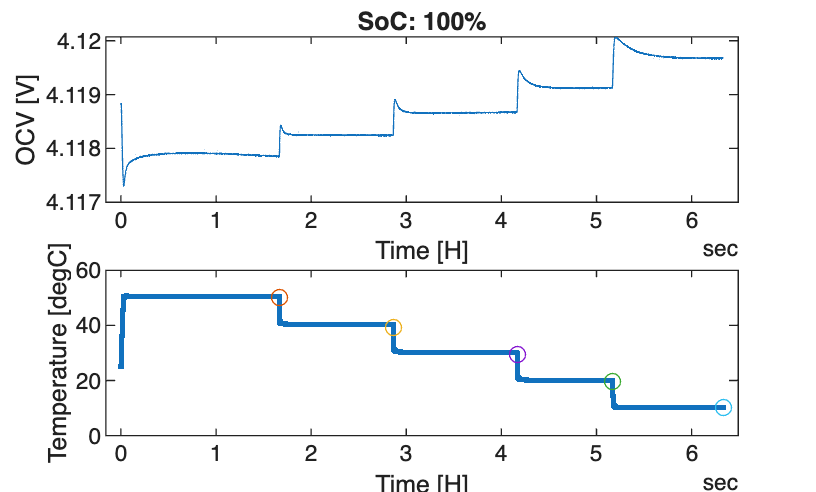

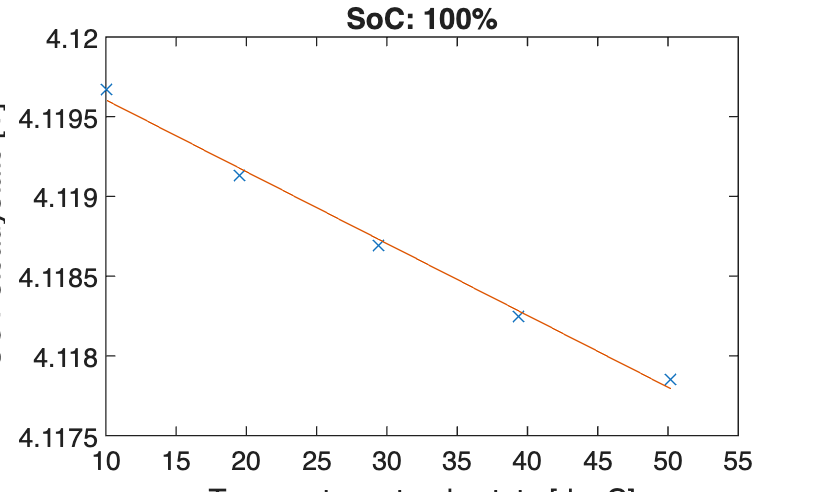

dataPth = what('Measurement_Data/measurements_Aug2023').path;
potTextFilesInfo = dir(fullfile(dataPth,"*Potentiometric.txt"));
hdrNames = ["time", "TEC1", "TEC2", "BoxTop", "TabAnode", "SurfaceBottomAnode", "SurfaceTopAnode", "SurfaceBottomCathode", "SurfaceTopCathode", "TabCathode", "SurfaceTopCenter", "SurfaceBottomCenter", "CoolingBlockTop", "Ambient", "U"];
z = [0:5:100]; % SoC break points

for zz = 1:numel(z)
    filePath = fullfile(dataPth,potTextFilesInfo(zz).name);
    imOpts = detectImportOptions(filePath);
    imOpts.VariableNames = hdrNames;
    potData = readtable(filePath,imOpts);
    Time_s = seconds(potData.(1) - potData.(1)(1)); % Reset time to 0 seconds
    potData.Time_s = Time_s;
    potData = table2timetable(potData,"RowTimes",Time_s);
    potDuration = hours(potData.Time(end))
    caloricTemp = CaloricCellTemperature(potData);
    time = caloricTemp.Time;
    temp = caloricTemp.meanCaloric;
    ocv = potData.U;

    idx50 = find(temp > 49.5 & temp < 50.5, 1, 'last');
    idx40 = find(temp > 39.3 & temp < 40.3, 1,'last');
    idx30 = find(temp > 29.01 & temp < 30.01, 1,'last');
    idx20 = find(temp > 19.01 & temp < 20.01, 1,'last');
    idx10 = find(temp > 9.05 & temp < 10.5, 1,'last');

    idxSS = [idx50,idx40,idx30,idx20,idx10];

    ssOCV = ocv(idxSS);
    ssTemp = temp(idxSS);

    tempSelected = ssTemp;
    ocvSelected = ssOCV*1000; % [mV]

    % Best fit
    K = [ones(size(tempSelected)),tempSelected];    % Regressor matrix;
    [dUdTP_Tmp,dudTP_info] = Lls(K,ocvSelected);
    dUdTFit = polyval(flipud(dUdTP_Tmp),ssTemp)/1000;       % [V]

    dUdTP(zz,1) = dUdTP_Tmp(2);
    dUdTP_std(zz,1) = sqrt(dudTP_info.paraVar(2));

    figure
    ax(1) = subplot(2,1,1);

    plot(time/3600,potData.U);
    xlabel("Time [H]"); ylabel("OCV [V]"); title(['SoC: ' num2str(z(zz)) '%'])
    ax(2) =  subplot(2,1,2);
    plot(time/3600,temp,'. -',...
         time(idx50)/3600,temp(idx50),'o',...
         time(idx40)/3600,temp(idx40),'o',...
         time(idx30)/3600,temp(idx30),'o',...
         time(idx20)/3600,temp(idx20),'o',...
         time(idx10)/3600,temp(idx10),'o')
    xlabel("Time [H]"); ylabel("Temperature [degC]")

    figure
    plot(ssTemp,ssOCV,'x',ssTemp,dUdTFit,'-')
    xlabel("Temperature steady-state [degC]"); ylabel("OCV steadystate [V]"); title(['SoC: ' num2str(z(zz)) '%'])

end

## Plot dUdT for Kernel, potentiometric and Potentiometric from Schmidt et al.

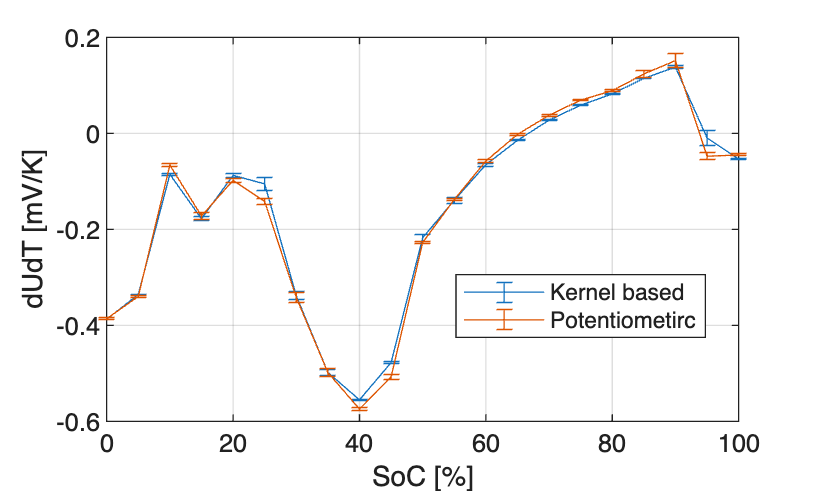

% load("potentiometricSchmidt.mat")
figure
[z_sort,idx_sort] = sort(z);
errorbar(z_sort,dUdTK(idx_sort),dUdTK_std(idx_sort))
hold on
errorbar(z_sort,dUdTP(idx_sort),dUdTP_std(idx_sort)); grid on;

xlabel("SoC [%]"); ylabel("dUdT [mV/K]")
legend(["Kernel based","Potentiometirc"],"Location","best")

% legend(["Freq Controlled","Potentiometirc","Pot. Schmidt et al. 2014"],"Location","best")

function [caloricTemp] = CaloricCellTemperature(potData)
p = EntropyCoeffEstimator();

alphaCuCell = p.cellThermalProperties.copperConductivity_wpmk/p.cellThermalProperties.copperThickness_m; %Approximation heat conductivity Cu-plate to Cell, W/(m^2*K)
KeyFigures.Nu2Infinity = (pi^2)/2;
KeyFigures.Bi = (alphaCuCell * p.cellThermalProperties.cellThickness_m)/ p.cellThermalProperties.cellConductivity_wpmk; %Biot-Number
KeyFigures.NuiInfinity = (4+p.cellThermalProperties.GeoFactor + KeyFigures.Bi)/(1+(KeyFigures.Bi/KeyFigures.Nu2Infinity));


MeanTemp.TECRef = (potData.TEC1 + potData.TEC2)/2;
MeanTemp.Caloric = (potData.SurfaceTopCenter + potData.SurfaceTopCathode + potData.SurfaceTopAnode + potData.SurfaceBottomCenter + potData.SurfaceBottomCathode)/5; %für erste Zeile kann wegen t=0 keine kalorische Mitteltemperatur berechnet werden
setTemp = MeanTemp.TECRef;

Zeilen = size(MeanTemp.TECRef,1);
t = 2;
Caloric(1,1) = 0;
for ii = 2:Zeilen
    if isequal(setTemp(ii), setTemp(ii-1))
        %Kalorische Mitteltemperatur
        KeyFigures.Fo(ii) = (p.cellThermalProperties.cellConductivity_wpmk*t)/(p.cellThermalProperties.cellThickness_m^2 * p.cellThermalProperties.cellDenisty_kgpm3 * p.cellThermalProperties.cellSpecificHeatCapacity_Jp);
        KeyFigures.Nui0(ii) = (sqrt(pi)+ 10*KeyFigures.Bi*sqrt(KeyFigures.Fo(ii)))/(1+5*KeyFigures.Bi*sqrt(pi*KeyFigures.Fo(ii)))*1/sqrt(KeyFigures.Fo(ii));
        KeyFigures.Nui(ii) = sqrt((KeyFigures.NuiInfinity^2)-(0.4^2)+(KeyFigures.Nui0(ii) + 0.4)^2);
        KeyFigures.NTUi(ii) = (p.cellThermalProperties.GeoFactor * KeyFigures.Fo(ii))/((1/KeyFigures.Bi) + (1/KeyFigures.Nui(ii)));
        Caloric(ii,1) = (MeanTemp.TECRef(ii) + (MeanTemp.Caloric(ii-(t/2))-MeanTemp.TECRef(ii))*exp(-KeyFigures.NTUi(ii)));
        t = t+2;
    else
        t = 2;
        %Kalorische Mitteltemperatur
        KeyFigures.Fo(ii) = (p.cellThermalProperties.cellConductivity_wpmk*t)/(p.cellThermalProperties.cellThickness_m^2 * p.cellThermalProperties.cellDenisty_kgpm3 * p.cellThermalProperties.cellSpecificHeatCapacity_Jp);
        KeyFigures.Nui0(ii) = ((sqrt(pi)+ 10*KeyFigures.Bi*sqrt(KeyFigures.Fo(ii)))/(1+5*KeyFigures.Bi*sqrt(pi*KeyFigures.Fo(ii))))*(1./sqrt(KeyFigures.Fo(ii)));
        KeyFigures.Nui(ii) = sqrt(KeyFigures.NuiInfinity^2-0.4^2.+(KeyFigures.Nui0(ii) + 0.4)^2);
        KeyFigures.NTUi(ii) = (p.cellThermalProperties.GeoFactor * KeyFigures.Fo(ii))/((1/KeyFigures.Bi) + (1/KeyFigures.Nui(ii)));
        Caloric(ii,1) =(MeanTemp.TECRef(ii) + (MeanTemp.Caloric(ii-1) - MeanTemp.TECRef(ii))*exp(-KeyFigures.NTUi(ii)));
    end

end
caloricTemp = timetable(potData.Time_s,Caloric,MeanTemp.Caloric,MeanTemp.TECRef,'VariableNames',["dynamicCaloric","meanCaloric","meanTecRef"]);
end